testImageIdx = randi([1,3])

testImageIdx = 1

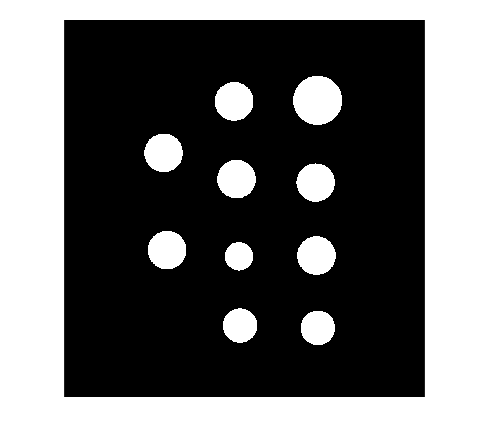

testCoinImage = imread("testCoinImage"+testImageIdx+".png");
%call segmentation function
[testCoinMask,maskedTestCoin]= segmentImageCoinTest(testCoinImage);
% Shrink the coin mask.
se = strel('disk', 15, 6);
testCoinMask2 = testCoinMask;
imshow(testCoinMask2)

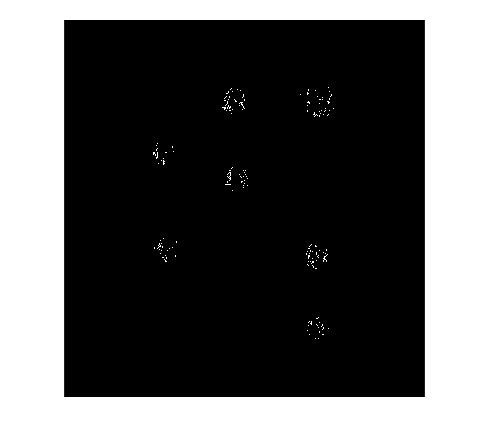

testCoinMask = imfill(testCoinMask, 'holes'); % Fill any holes in it.
testCoinMask = imerode(testCoinMask, se); % Shrink by 3 layers of pixels.

imgFilt = imgaussfilt(maskedTestCoin,0.5,Padding="circular",FilterDomain="frequency",FilterSize=1);
faceEdgeMask= edge(imgFilt,"sobel",0.075,"both");
faceEdgeMask(~testCoinMask) = false;
imshow(faceEdgeMask)

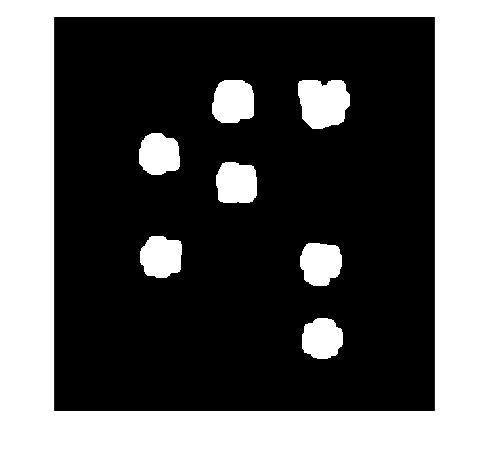

%Passed

faceEdgeMask = imresize(faceEdgeMask, [600 580]);

faceEdgeMaskDilate = imdilate(faceEdgeMask,se);
imshow(faceEdgeMaskDilate)

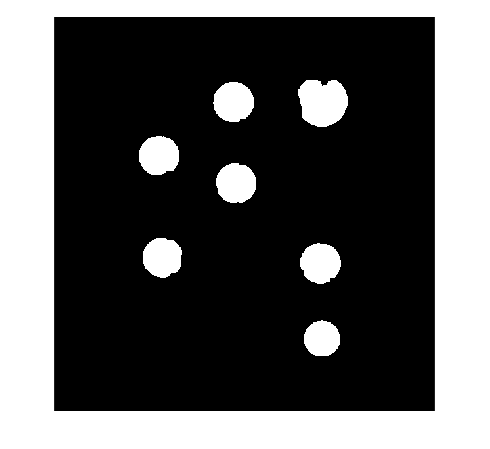

testCoinMask2 = imresize(testCoinMask2, [600 580]);
validCoinMask = faceEdgeMaskDilate & testCoinMask2;
imshow(validCoinMask)

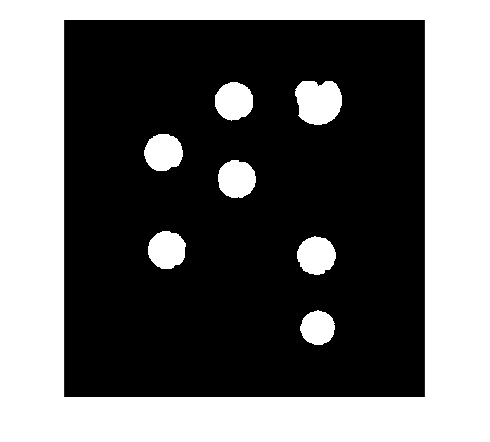

validCoinMask(~testCoinMask2) = 0;
validCoinMask = imresize(validCoinMask, [972 930]);
imshow(validCoinMask)



%It only works for Index 1
%If you want it to work perfectly just reduce some values for the dimes and
%nickels and it should be good to go.

nDimes_A = bwpropfilt(validCoinMask, 'Area', [4000, 5000]);
nDimes_B = regionprops(nDimes_A,'Area');
nDimes = size(nDimes_B,1);
nNickels_A = bwpropfilt(validCoinMask, 'Area', [6000, 7000]);
nNickels_B = regionprops(nNickels_A,'Area');
nNickels = size(nNickels_B,1)

nNickels = 1

nQuarters_A = bwpropfilt(validCoinMask, 'Area', [7000, 8000]);
nQuarters_B = regionprops(nQuarters_A,'Area');
nQuarters = size(nQuarters_B,1)

nQuarters = 5

nFiftyCents_A = bwpropfilt(validCoinMask, 'Area', [10000, 13000]);
nFiftyCents_B = regionprops(nFiftyCents_A,'Area');
nFiftyCents = size(nFiftyCents_B,1)

nFiftyCents = 1

USD = (0.1*nDimes)+(0.05*nNickels)+(0.25*nQuarters)+(nFiftyCents*0.50)

USD = 1.8000